% Clear workspace
clearvars; close all; clc;

% Base path (assuming script is run from the project folder)
base_path = pwd;

% Relative paths for data and output folders
data_folder = fullfile(base_path, 'DATA', 'VibrationTestData');
output_folder = fullfile(base_path, 'DATA', 'PreprocessedData');

% Sampling frequency and filter settings
fs = 200; % Sampling frequency
fc_low = 5;  % Low cutoff frequency for the bandpass filter
fc_high = 90; % High cutoff frequency for the bandpass filter
[b1, a1] = butter(1, fc_high / (fs / 2), 'low');
[b2, a2] = butter(3, fc_low / (fs / 2), 'high');

% List of test folders manually excluding Test_23 and Test_24
test_folders = setdiff(1:25, [23, 24]); % Tests 1 to 25 but exclude 23 and 24

% Start the total timer
total_tic = tic;

% Define augmentation parameters
num_augmentations = 5; % Number of augmented versions per original sample
noise_std = 0.00001; % Reduced standard deviation for Gaussian noise (about 10% of baseline)

% Loop through the test folders
all_files = {}; % Collect all file paths for later use
all_folders = {}; % Store corresponding folder paths

for test_num = test_folders
    % Define the current folder path
    current_test_folder = sprintf('Test_%d', test_num);
    full_test_path = fullfile(data_folder, current_test_folder);
    
    % Get list of all CSV files in the folder
    csv_files = dir(fullfile(full_test_path, '*.csv'));
    
    % Loop through each CSV file found in the folder
    for f = 1:length(csv_files)
        file_name = csv_files(f).name; % Get the file name
        file_path = fullfile(full_test_path, file_name); % Full file path
        
        if isfile(file_path) % Check if the file exists (safety check)
            all_files{end+1} = file_name; % Append to file list
            all_folders{end+1} = full_test_path; % Append corresponding folder
        else
            warning('File not found: %s', file_path); % Warn if file is missing
        end
    end
end

% Verify that files were found
if isempty(all_files)
    error('No files were found in the specified data folder. Please check the folder paths and files.');
end

% Select a random dataset for plotting
random_idx = randi(length(all_files));
selected_file = all_files{random_idx};
selected_folder = all_folders{random_idx};

% Loop through all files for processing and exporting
for i = 1:length(all_files)
    current_file = all_files{i};
    current_folder = all_folders{i};
    file_path = fullfile(current_folder, current_file);
    opts = detectImportOptions(file_path);
    opts.VariableNames{1} = 'SamplingTime';
    data = readtable(file_path, opts);

    % Ensure 'SamplingTime' is a datetime type
    if iscell(data.SamplingTime)
        data.SamplingTime = datetime(data.SamplingTime, 'InputFormat', 'yyyy/MM/dd HH:mm:ss.SSS');
    end

    % Rename the columns to appropriate sensor names
    sensor_names = {'SamplingTime', ...
        'Sensor_1_X', 'Sensor_1_Y', 'Sensor_1_Z', ...
        'Sensor_2_X', 'Sensor_2_Y', 'Sensor_2_Z', ...
        'Sensor_3_X', 'Sensor_3_Y', 'Sensor_3_Z', ...
        'Sensor_4_X', 'Sensor_4_Y', 'Sensor_4_Z'};
    data.Properties.VariableNames = sensor_names;

    % Extract acceleration data (excluding time)
    acc_data = data{:, 2:end};  % Exclude the first column (time)
    time_data = seconds(data.SamplingTime - data.SamplingTime(1)); % Convert timestamp to relative time in seconds

    % Step 1: Center the raw data by subtracting the mean
    centered_acc_data = acc_data - mean(acc_data);

    % Step 2: Apply the low-high bandpass filter to the centered data
    filtered_acc_data = zeros(size(centered_acc_data));
    for j = 1:size(centered_acc_data, 2)
        filtered_acc_data_j = filtfilt(b1, a1, centered_acc_data(:, j)); % Apply the low-pass filter
        filtered_acc_data(:, j) = filtfilt(b2, a2, filtered_acc_data_j); % Apply the high-pass filter
    end

    % Export the original filtered acceleration data for the current file
    output_file_name_acc = sprintf('Filtered_Acc_Data_%s.csv', erase(current_file, '.csv'));
    filtered_data_table = array2table(filtered_acc_data, 'VariableNames', sensor_names(2:end));
    filtered_data_table.SamplingTime = data.SamplingTime; % Add time data
    filtered_data_table = filtered_data_table(:, [end, 1:end-1]); % Move SamplingTime to the first column
    writetable(filtered_data_table, fullfile(output_folder, output_file_name_acc));

    disp(['Exported filtered acceleration data for ', current_file, ' to ', output_file_name_acc]);

    % Step 3: Apply data augmentation by adding noise directly to the filtered data
    for n = 1:num_augmentations
        % Add Gaussian noise to the filtered signal
        augmented_acc_data = filtered_acc_data + noise_std * randn(size(filtered_acc_data));

        % Save the augmented data directly, without additional filtering
        augmented_file_name = sprintf('Filtered_Acc_Data_%s_aug%d.csv', erase(current_file, '.csv'), n);
        augmented_data_table = array2table(augmented_acc_data, 'VariableNames', sensor_names(2:end));
        augmented_data_table.SamplingTime = data.SamplingTime;
        augmented_data_table = augmented_data_table(:, [end, 1:end-1]); % Move SamplingTime to the first column
        writetable(augmented_data_table, fullfile(output_folder, augmented_file_name));

        disp(['Exported augmented data for ', current_file, ' as ', augmented_file_name]);

        % If this is the randomly selected file, store for plotting
        if i == random_idx && n == 1 % Take the first augmented version for plotting
            plot_augmented_acc_data = augmented_acc_data;
        end
    end

    % If this is the randomly selected file, store the data for plotting
    if i == random_idx
        plot_time_data = time_data;
        plot_acc_data = acc_data;
        plot_centered_acc_data = centered_acc_data;
        plot_filtered_acc_data = filtered_acc_data;
    end
end

Exported filtered acceleration data for Test_1_M_V.csv to Filtered_Acc_Data_Test_1_M_V.csv


Exported augmented data for Test_1_M_V.csv as Filtered_Acc_Data_Test_1_M_V_aug1.csv
Exported augmented data for Test_1_M_V.csv as Filtered_Acc_Data_Test_1_M_V_aug2.csv
Exported augmented data for Test_1_M_V.csv as Filtered_Acc_Data_Test_1_M_V_aug3.csv
Exported augmented data for Test_1_M_V.csv as Filtered_Acc_Data_Test_1_M_V_aug4.csv
Exported augmented data for Test_1_M_V.csv as Filtered_Acc_Data_Test_1_M_V_aug5.csv


Exported filtered acceleration data for Test_1_N_H.csv to Filtered_Acc_Data_Test_1_N_H.csv


Exported augmented data for Test_1_N_H.csv as Filtered_Acc_Data_Test_1_N_H_aug1.csv
Exported augmented data for Test_1_N_H.csv as Filtered_Acc_Data_Test_1_N_H_aug2.csv
Exported augmented data for Test_1_N_H.csv as Filtered_Acc_Data_Test_1_N_H_aug3.csv
Exported augmented data for Test_1_N_H.csv as Filtered_Acc_Data_Test_1_N_H_aug4.csv
Exported augmented data for Test_1_N_H.csv as Filtered_Acc_Data_Test_1_N_H_aug5.csv


Exported filtered acceleration data for Test_1_N_V.csv to Filtered_Acc_Data_Test_1_N_V.csv


Exported augmented data for Test_1_N_V.csv as Filtered_Acc_Data_Test_1_N_V_aug1.csv
Exported augmented data for Test_1_N_V.csv as Filtered_Acc_Data_Test_1_N_V_aug2.csv
Exported augmented data for Test_1_N_V.csv as Filtered_Acc_Data_Test_1_N_V_aug3.csv
Exported augmented data for Test_1_N_V.csv as Filtered_Acc_Data_Test_1_N_V_aug4.csv
Exported augmented data for Test_1_N_V.csv as Filtered_Acc_Data_Test_1_N_V_aug5.csv


Exported filtered acceleration data for Test_1_S_H.csv to Filtered_Acc_Data_Test_1_S_H.csv


Exported augmented data for Test_1_S_H.csv as Filtered_Acc_Data_Test_1_S_H_aug1.csv
Exported augmented data for Test_1_S_H.csv as Filtered_Acc_Data_Test_1_S_H_aug2.csv
Exported augmented data for Test_1_S_H.csv as Filtered_Acc_Data_Test_1_S_H_aug3.csv
Exported augmented data for Test_1_S_H.csv as Filtered_Acc_Data_Test_1_S_H_aug4.csv
Exported augmented data for Test_1_S_H.csv as Filtered_Acc_Data_Test_1_S_H_aug5.csv


Exported filtered acceleration data for Test_1_S_V.csv to Filtered_Acc_Data_Test_1_S_V.csv


Exported augmented data for Test_1_S_V.csv as Filtered_Acc_Data_Test_1_S_V_aug1.csv
Exported augmented data for Test_1_S_V.csv as Filtered_Acc_Data_Test_1_S_V_aug2.csv
Exported augmented data for Test_1_S_V.csv as Filtered_Acc_Data_Test_1_S_V_aug3.csv
Exported augmented data for Test_1_S_V.csv as Filtered_Acc_Data_Test_1_S_V_aug4.csv
Exported augmented data for Test_1_S_V.csv as Filtered_Acc_Data_Test_1_S_V_aug5.csv


Exported filtered acceleration data for Test_2_M_V.csv to Filtered_Acc_Data_Test_2_M_V.csv


Exported augmented data for Test_2_M_V.csv as Filtered_Acc_Data_Test_2_M_V_aug1.csv
Exported augmented data for Test_2_M_V.csv as Filtered_Acc_Data_Test_2_M_V_aug2.csv
Exported augmented data for Test_2_M_V.csv as Filtered_Acc_Data_Test_2_M_V_aug3.csv
Exported augmented data for Test_2_M_V.csv as Filtered_Acc_Data_Test_2_M_V_aug4.csv
Exported augmented data for Test_2_M_V.csv as Filtered_Acc_Data_Test_2_M_V_aug5.csv


Exported filtered acceleration data for Test_2_N_H.csv to Filtered_Acc_Data_Test_2_N_H.csv


Exported augmented data for Test_2_N_H.csv as Filtered_Acc_Data_Test_2_N_H_aug1.csv
Exported augmented data for Test_2_N_H.csv as Filtered_Acc_Data_Test_2_N_H_aug2.csv
Exported augmented data for Test_2_N_H.csv as Filtered_Acc_Data_Test_2_N_H_aug3.csv
Exported augmented data for Test_2_N_H.csv as Filtered_Acc_Data_Test_2_N_H_aug4.csv
Exported augmented data for Test_2_N_H.csv as Filtered_Acc_Data_Test_2_N_H_aug5.csv


Exported filtered acceleration data for Test_2_N_V.csv to Filtered_Acc_Data_Test_2_N_V.csv


Exported augmented data for Test_2_N_V.csv as Filtered_Acc_Data_Test_2_N_V_aug1.csv
Exported augmented data for Test_2_N_V.csv as Filtered_Acc_Data_Test_2_N_V_aug2.csv
Exported augmented data for Test_2_N_V.csv as Filtered_Acc_Data_Test_2_N_V_aug3.csv
Exported augmented data for Test_2_N_V.csv as Filtered_Acc_Data_Test_2_N_V_aug4.csv
Exported augmented data for Test_2_N_V.csv as Filtered_Acc_Data_Test_2_N_V_aug5.csv


Exported filtered acceleration data for Test_2_S_H.csv to Filtered_Acc_Data_Test_2_S_H.csv


Exported augmented data for Test_2_S_H.csv as Filtered_Acc_Data_Test_2_S_H_aug1.csv
Exported augmented data for Test_2_S_H.csv as Filtered_Acc_Data_Test_2_S_H_aug2.csv
Exported augmented data for Test_2_S_H.csv as Filtered_Acc_Data_Test_2_S_H_aug3.csv
Exported augmented data for Test_2_S_H.csv as Filtered_Acc_Data_Test_2_S_H_aug4.csv
Exported augmented data for Test_2_S_H.csv as Filtered_Acc_Data_Test_2_S_H_aug5.csv


Exported filtered acceleration data for Test_2_S_V.csv to Filtered_Acc_Data_Test_2_S_V.csv


Exported augmented data for Test_2_S_V.csv as Filtered_Acc_Data_Test_2_S_V_aug1.csv
Exported augmented data for Test_2_S_V.csv as Filtered_Acc_Data_Test_2_S_V_aug2.csv
Exported augmented data for Test_2_S_V.csv as Filtered_Acc_Data_Test_2_S_V_aug3.csv
Exported augmented data for Test_2_S_V.csv as Filtered_Acc_Data_Test_2_S_V_aug4.csv
Exported augmented data for Test_2_S_V.csv as Filtered_Acc_Data_Test_2_S_V_aug5.csv


Exported filtered acceleration data for Test_3_M_V.csv to Filtered_Acc_Data_Test_3_M_V.csv


Exported augmented data for Test_3_M_V.csv as Filtered_Acc_Data_Test_3_M_V_aug1.csv
Exported augmented data for Test_3_M_V.csv as Filtered_Acc_Data_Test_3_M_V_aug2.csv
Exported augmented data for Test_3_M_V.csv as Filtered_Acc_Data_Test_3_M_V_aug3.csv
Exported augmented data for Test_3_M_V.csv as Filtered_Acc_Data_Test_3_M_V_aug4.csv
Exported augmented data for Test_3_M_V.csv as Filtered_Acc_Data_Test_3_M_V_aug5.csv


Exported filtered acceleration data for Test_3_N_H.csv to Filtered_Acc_Data_Test_3_N_H.csv


Exported augmented data for Test_3_N_H.csv as Filtered_Acc_Data_Test_3_N_H_aug1.csv
Exported augmented data for Test_3_N_H.csv as Filtered_Acc_Data_Test_3_N_H_aug2.csv
Exported augmented data for Test_3_N_H.csv as Filtered_Acc_Data_Test_3_N_H_aug3.csv
Exported augmented data for Test_3_N_H.csv as Filtered_Acc_Data_Test_3_N_H_aug4.csv
Exported augmented data for Test_3_N_H.csv as Filtered_Acc_Data_Test_3_N_H_aug5.csv


Exported filtered acceleration data for Test_3_N_V.csv to Filtered_Acc_Data_Test_3_N_V.csv


Exported augmented data for Test_3_N_V.csv as Filtered_Acc_Data_Test_3_N_V_aug1.csv
Exported augmented data for Test_3_N_V.csv as Filtered_Acc_Data_Test_3_N_V_aug2.csv
Exported augmented data for Test_3_N_V.csv as Filtered_Acc_Data_Test_3_N_V_aug3.csv
Exported augmented data for Test_3_N_V.csv as Filtered_Acc_Data_Test_3_N_V_aug4.csv
Exported augmented data for Test_3_N_V.csv as Filtered_Acc_Data_Test_3_N_V_aug5.csv


Exported filtered acceleration data for Test_3_S_H.csv to Filtered_Acc_Data_Test_3_S_H.csv


Exported augmented data for Test_3_S_H.csv as Filtered_Acc_Data_Test_3_S_H_aug1.csv
Exported augmented data for Test_3_S_H.csv as Filtered_Acc_Data_Test_3_S_H_aug2.csv
Exported augmented data for Test_3_S_H.csv as Filtered_Acc_Data_Test_3_S_H_aug3.csv
Exported augmented data for Test_3_S_H.csv as Filtered_Acc_Data_Test_3_S_H_aug4.csv
Exported augmented data for Test_3_S_H.csv as Filtered_Acc_Data_Test_3_S_H_aug5.csv


Exported filtered acceleration data for Test_3_S_V.csv to Filtered_Acc_Data_Test_3_S_V.csv


Exported augmented data for Test_3_S_V.csv as Filtered_Acc_Data_Test_3_S_V_aug1.csv
Exported augmented data for Test_3_S_V.csv as Filtered_Acc_Data_Test_3_S_V_aug2.csv
Exported augmented data for Test_3_S_V.csv as Filtered_Acc_Data_Test_3_S_V_aug3.csv
Exported augmented data for Test_3_S_V.csv as Filtered_Acc_Data_Test_3_S_V_aug4.csv
Exported augmented data for Test_3_S_V.csv as Filtered_Acc_Data_Test_3_S_V_aug5.csv


Exported filtered acceleration data for Test_4_M_V.csv to Filtered_Acc_Data_Test_4_M_V.csv


Exported augmented data for Test_4_M_V.csv as Filtered_Acc_Data_Test_4_M_V_aug1.csv
Exported augmented data for Test_4_M_V.csv as Filtered_Acc_Data_Test_4_M_V_aug2.csv
Exported augmented data for Test_4_M_V.csv as Filtered_Acc_Data_Test_4_M_V_aug3.csv
Exported augmented data for Test_4_M_V.csv as Filtered_Acc_Data_Test_4_M_V_aug4.csv
Exported augmented data for Test_4_M_V.csv as Filtered_Acc_Data_Test_4_M_V_aug5.csv


Exported filtered acceleration data for Test_4_N_H.csv to Filtered_Acc_Data_Test_4_N_H.csv


Exported augmented data for Test_4_N_H.csv as Filtered_Acc_Data_Test_4_N_H_aug1.csv
Exported augmented data for Test_4_N_H.csv as Filtered_Acc_Data_Test_4_N_H_aug2.csv
Exported augmented data for Test_4_N_H.csv as Filtered_Acc_Data_Test_4_N_H_aug3.csv
Exported augmented data for Test_4_N_H.csv as Filtered_Acc_Data_Test_4_N_H_aug4.csv
Exported augmented data for Test_4_N_H.csv as Filtered_Acc_Data_Test_4_N_H_aug5.csv


Exported filtered acceleration data for Test_4_S_H.csv to Filtered_Acc_Data_Test_4_S_H.csv


Exported augmented data for Test_4_S_H.csv as Filtered_Acc_Data_Test_4_S_H_aug1.csv
Exported augmented data for Test_4_S_H.csv as Filtered_Acc_Data_Test_4_S_H_aug2.csv
Exported augmented data for Test_4_S_H.csv as Filtered_Acc_Data_Test_4_S_H_aug3.csv
Exported augmented data for Test_4_S_H.csv as Filtered_Acc_Data_Test_4_S_H_aug4.csv
Exported augmented data for Test_4_S_H.csv as Filtered_Acc_Data_Test_4_S_H_aug5.csv


Exported filtered acceleration data for Test_4_S_V.csv to Filtered_Acc_Data_Test_4_S_V.csv


Exported augmented data for Test_4_S_V.csv as Filtered_Acc_Data_Test_4_S_V_aug1.csv
Exported augmented data for Test_4_S_V.csv as Filtered_Acc_Data_Test_4_S_V_aug2.csv
Exported augmented data for Test_4_S_V.csv as Filtered_Acc_Data_Test_4_S_V_aug3.csv
Exported augmented data for Test_4_S_V.csv as Filtered_Acc_Data_Test_4_S_V_aug4.csv
Exported augmented data for Test_4_S_V.csv as Filtered_Acc_Data_Test_4_S_V_aug5.csv


Exported filtered acceleration data for Test_4_S_V_2.csv to Filtered_Acc_Data_Test_4_S_V_2.csv


Exported augmented data for Test_4_S_V_2.csv as Filtered_Acc_Data_Test_4_S_V_2_aug1.csv
Exported augmented data for Test_4_S_V_2.csv as Filtered_Acc_Data_Test_4_S_V_2_aug2.csv
Exported augmented data for Test_4_S_V_2.csv as Filtered_Acc_Data_Test_4_S_V_2_aug3.csv
Exported augmented data for Test_4_S_V_2.csv as Filtered_Acc_Data_Test_4_S_V_2_aug4.csv
Exported augmented data for Test_4_S_V_2.csv as Filtered_Acc_Data_Test_4_S_V_2_aug5.csv


Exported filtered acceleration data for Test_5_M_V.csv to Filtered_Acc_Data_Test_5_M_V.csv


Exported augmented data for Test_5_M_V.csv as Filtered_Acc_Data_Test_5_M_V_aug1.csv
Exported augmented data for Test_5_M_V.csv as Filtered_Acc_Data_Test_5_M_V_aug2.csv
Exported augmented data for Test_5_M_V.csv as Filtered_Acc_Data_Test_5_M_V_aug3.csv
Exported augmented data for Test_5_M_V.csv as Filtered_Acc_Data_Test_5_M_V_aug4.csv
Exported augmented data for Test_5_M_V.csv as Filtered_Acc_Data_Test_5_M_V_aug5.csv


Exported filtered acceleration data for Test_5_N_H.csv to Filtered_Acc_Data_Test_5_N_H.csv


Exported augmented data for Test_5_N_H.csv as Filtered_Acc_Data_Test_5_N_H_aug1.csv
Exported augmented data for Test_5_N_H.csv as Filtered_Acc_Data_Test_5_N_H_aug2.csv
Exported augmented data for Test_5_N_H.csv as Filtered_Acc_Data_Test_5_N_H_aug3.csv
Exported augmented data for Test_5_N_H.csv as Filtered_Acc_Data_Test_5_N_H_aug4.csv
Exported augmented data for Test_5_N_H.csv as Filtered_Acc_Data_Test_5_N_H_aug5.csv


Exported filtered acceleration data for Test_5_N_V.csv to Filtered_Acc_Data_Test_5_N_V.csv


Exported augmented data for Test_5_N_V.csv as Filtered_Acc_Data_Test_5_N_V_aug1.csv
Exported augmented data for Test_5_N_V.csv as Filtered_Acc_Data_Test_5_N_V_aug2.csv
Exported augmented data for Test_5_N_V.csv as Filtered_Acc_Data_Test_5_N_V_aug3.csv
Exported augmented data for Test_5_N_V.csv as Filtered_Acc_Data_Test_5_N_V_aug4.csv
Exported augmented data for Test_5_N_V.csv as Filtered_Acc_Data_Test_5_N_V_aug5.csv


Exported filtered acceleration data for Test_5_S_H.csv to Filtered_Acc_Data_Test_5_S_H.csv


Exported augmented data for Test_5_S_H.csv as Filtered_Acc_Data_Test_5_S_H_aug1.csv
Exported augmented data for Test_5_S_H.csv as Filtered_Acc_Data_Test_5_S_H_aug2.csv
Exported augmented data for Test_5_S_H.csv as Filtered_Acc_Data_Test_5_S_H_aug3.csv
Exported augmented data for Test_5_S_H.csv as Filtered_Acc_Data_Test_5_S_H_aug4.csv
Exported augmented data for Test_5_S_H.csv as Filtered_Acc_Data_Test_5_S_H_aug5.csv


Exported filtered acceleration data for Test_5_S_V.csv to Filtered_Acc_Data_Test_5_S_V.csv


Exported augmented data for Test_5_S_V.csv as Filtered_Acc_Data_Test_5_S_V_aug1.csv
Exported augmented data for Test_5_S_V.csv as Filtered_Acc_Data_Test_5_S_V_aug2.csv
Exported augmented data for Test_5_S_V.csv as Filtered_Acc_Data_Test_5_S_V_aug3.csv
Exported augmented data for Test_5_S_V.csv as Filtered_Acc_Data_Test_5_S_V_aug4.csv
Exported augmented data for Test_5_S_V.csv as Filtered_Acc_Data_Test_5_S_V_aug5.csv


Exported filtered acceleration data for Test_6_M_V.csv to Filtered_Acc_Data_Test_6_M_V.csv


Exported augmented data for Test_6_M_V.csv as Filtered_Acc_Data_Test_6_M_V_aug1.csv
Exported augmented data for Test_6_M_V.csv as Filtered_Acc_Data_Test_6_M_V_aug2.csv
Exported augmented data for Test_6_M_V.csv as Filtered_Acc_Data_Test_6_M_V_aug3.csv
Exported augmented data for Test_6_M_V.csv as Filtered_Acc_Data_Test_6_M_V_aug4.csv
Exported augmented data for Test_6_M_V.csv as Filtered_Acc_Data_Test_6_M_V_aug5.csv


Exported filtered acceleration data for Test_6_N_H.csv to Filtered_Acc_Data_Test_6_N_H.csv


Exported augmented data for Test_6_N_H.csv as Filtered_Acc_Data_Test_6_N_H_aug1.csv
Exported augmented data for Test_6_N_H.csv as Filtered_Acc_Data_Test_6_N_H_aug2.csv
Exported augmented data for Test_6_N_H.csv as Filtered_Acc_Data_Test_6_N_H_aug3.csv
Exported augmented data for Test_6_N_H.csv as Filtered_Acc_Data_Test_6_N_H_aug4.csv
Exported augmented data for Test_6_N_H.csv as Filtered_Acc_Data_Test_6_N_H_aug5.csv


Exported filtered acceleration data for Test_6_N_V.csv to Filtered_Acc_Data_Test_6_N_V.csv


Exported augmented data for Test_6_N_V.csv as Filtered_Acc_Data_Test_6_N_V_aug1.csv
Exported augmented data for Test_6_N_V.csv as Filtered_Acc_Data_Test_6_N_V_aug2.csv
Exported augmented data for Test_6_N_V.csv as Filtered_Acc_Data_Test_6_N_V_aug3.csv
Exported augmented data for Test_6_N_V.csv as Filtered_Acc_Data_Test_6_N_V_aug4.csv
Exported augmented data for Test_6_N_V.csv as Filtered_Acc_Data_Test_6_N_V_aug5.csv


Exported filtered acceleration data for Test_6_S_H.csv to Filtered_Acc_Data_Test_6_S_H.csv


Exported augmented data for Test_6_S_H.csv as Filtered_Acc_Data_Test_6_S_H_aug1.csv
Exported augmented data for Test_6_S_H.csv as Filtered_Acc_Data_Test_6_S_H_aug2.csv
Exported augmented data for Test_6_S_H.csv as Filtered_Acc_Data_Test_6_S_H_aug3.csv
Exported augmented data for Test_6_S_H.csv as Filtered_Acc_Data_Test_6_S_H_aug4.csv
Exported augmented data for Test_6_S_H.csv as Filtered_Acc_Data_Test_6_S_H_aug5.csv


Exported filtered acceleration data for Test_6_S_V.csv to Filtered_Acc_Data_Test_6_S_V.csv


Exported augmented data for Test_6_S_V.csv as Filtered_Acc_Data_Test_6_S_V_aug1.csv
Exported augmented data for Test_6_S_V.csv as Filtered_Acc_Data_Test_6_S_V_aug2.csv
Exported augmented data for Test_6_S_V.csv as Filtered_Acc_Data_Test_6_S_V_aug3.csv
Exported augmented data for Test_6_S_V.csv as Filtered_Acc_Data_Test_6_S_V_aug4.csv
Exported augmented data for Test_6_S_V.csv as Filtered_Acc_Data_Test_6_S_V_aug5.csv


Exported filtered acceleration data for Test_7_M_V.csv to Filtered_Acc_Data_Test_7_M_V.csv


Exported augmented data for Test_7_M_V.csv as Filtered_Acc_Data_Test_7_M_V_aug1.csv
Exported augmented data for Test_7_M_V.csv as Filtered_Acc_Data_Test_7_M_V_aug2.csv
Exported augmented data for Test_7_M_V.csv as Filtered_Acc_Data_Test_7_M_V_aug3.csv
Exported augmented data for Test_7_M_V.csv as Filtered_Acc_Data_Test_7_M_V_aug4.csv
Exported augmented data for Test_7_M_V.csv as Filtered_Acc_Data_Test_7_M_V_aug5.csv


Exported filtered acceleration data for Test_7_N_H.csv to Filtered_Acc_Data_Test_7_N_H.csv


Exported augmented data for Test_7_N_H.csv as Filtered_Acc_Data_Test_7_N_H_aug1.csv
Exported augmented data for Test_7_N_H.csv as Filtered_Acc_Data_Test_7_N_H_aug2.csv
Exported augmented data for Test_7_N_H.csv as Filtered_Acc_Data_Test_7_N_H_aug3.csv
Exported augmented data for Test_7_N_H.csv as Filtered_Acc_Data_Test_7_N_H_aug4.csv
Exported augmented data for Test_7_N_H.csv as Filtered_Acc_Data_Test_7_N_H_aug5.csv


Exported filtered acceleration data for Test_7_N_V.csv to Filtered_Acc_Data_Test_7_N_V.csv


Exported augmented data for Test_7_N_V.csv as Filtered_Acc_Data_Test_7_N_V_aug1.csv
Exported augmented data for Test_7_N_V.csv as Filtered_Acc_Data_Test_7_N_V_aug2.csv
Exported augmented data for Test_7_N_V.csv as Filtered_Acc_Data_Test_7_N_V_aug3.csv
Exported augmented data for Test_7_N_V.csv as Filtered_Acc_Data_Test_7_N_V_aug4.csv
Exported augmented data for Test_7_N_V.csv as Filtered_Acc_Data_Test_7_N_V_aug5.csv


Exported filtered acceleration data for Test_7_S_H.csv to Filtered_Acc_Data_Test_7_S_H.csv


Exported augmented data for Test_7_S_H.csv as Filtered_Acc_Data_Test_7_S_H_aug1.csv
Exported augmented data for Test_7_S_H.csv as Filtered_Acc_Data_Test_7_S_H_aug2.csv
Exported augmented data for Test_7_S_H.csv as Filtered_Acc_Data_Test_7_S_H_aug3.csv
Exported augmented data for Test_7_S_H.csv as Filtered_Acc_Data_Test_7_S_H_aug4.csv
Exported augmented data for Test_7_S_H.csv as Filtered_Acc_Data_Test_7_S_H_aug5.csv


Exported filtered acceleration data for Test_7_S_V.csv to Filtered_Acc_Data_Test_7_S_V.csv


Exported augmented data for Test_7_S_V.csv as Filtered_Acc_Data_Test_7_S_V_aug1.csv
Exported augmented data for Test_7_S_V.csv as Filtered_Acc_Data_Test_7_S_V_aug2.csv
Exported augmented data for Test_7_S_V.csv as Filtered_Acc_Data_Test_7_S_V_aug3.csv
Exported augmented data for Test_7_S_V.csv as Filtered_Acc_Data_Test_7_S_V_aug4.csv
Exported augmented data for Test_7_S_V.csv as Filtered_Acc_Data_Test_7_S_V_aug5.csv


Exported filtered acceleration data for Test_8_M_V.csv to Filtered_Acc_Data_Test_8_M_V.csv


Exported augmented data for Test_8_M_V.csv as Filtered_Acc_Data_Test_8_M_V_aug1.csv
Exported augmented data for Test_8_M_V.csv as Filtered_Acc_Data_Test_8_M_V_aug2.csv
Exported augmented data for Test_8_M_V.csv as Filtered_Acc_Data_Test_8_M_V_aug3.csv
Exported augmented data for Test_8_M_V.csv as Filtered_Acc_Data_Test_8_M_V_aug4.csv
Exported augmented data for Test_8_M_V.csv as Filtered_Acc_Data_Test_8_M_V_aug5.csv


Exported filtered acceleration data for Test_8_N_H.csv to Filtered_Acc_Data_Test_8_N_H.csv


Exported augmented data for Test_8_N_H.csv as Filtered_Acc_Data_Test_8_N_H_aug1.csv
Exported augmented data for Test_8_N_H.csv as Filtered_Acc_Data_Test_8_N_H_aug2.csv
Exported augmented data for Test_8_N_H.csv as Filtered_Acc_Data_Test_8_N_H_aug3.csv
Exported augmented data for Test_8_N_H.csv as Filtered_Acc_Data_Test_8_N_H_aug4.csv
Exported augmented data for Test_8_N_H.csv as Filtered_Acc_Data_Test_8_N_H_aug5.csv


Exported filtered acceleration data for Test_8_N_V.csv to Filtered_Acc_Data_Test_8_N_V.csv


Exported augmented data for Test_8_N_V.csv as Filtered_Acc_Data_Test_8_N_V_aug1.csv
Exported augmented data for Test_8_N_V.csv as Filtered_Acc_Data_Test_8_N_V_aug2.csv
Exported augmented data for Test_8_N_V.csv as Filtered_Acc_Data_Test_8_N_V_aug3.csv
Exported augmented data for Test_8_N_V.csv as Filtered_Acc_Data_Test_8_N_V_aug4.csv
Exported augmented data for Test_8_N_V.csv as Filtered_Acc_Data_Test_8_N_V_aug5.csv


Exported filtered acceleration data for Test_8_S_H.csv to Filtered_Acc_Data_Test_8_S_H.csv


Exported augmented data for Test_8_S_H.csv as Filtered_Acc_Data_Test_8_S_H_aug1.csv
Exported augmented data for Test_8_S_H.csv as Filtered_Acc_Data_Test_8_S_H_aug2.csv
Exported augmented data for Test_8_S_H.csv as Filtered_Acc_Data_Test_8_S_H_aug3.csv
Exported augmented data for Test_8_S_H.csv as Filtered_Acc_Data_Test_8_S_H_aug4.csv
Exported augmented data for Test_8_S_H.csv as Filtered_Acc_Data_Test_8_S_H_aug5.csv


Exported filtered acceleration data for Test_8_S_V.csv to Filtered_Acc_Data_Test_8_S_V.csv


Exported augmented data for Test_8_S_V.csv as Filtered_Acc_Data_Test_8_S_V_aug1.csv
Exported augmented data for Test_8_S_V.csv as Filtered_Acc_Data_Test_8_S_V_aug2.csv
Exported augmented data for Test_8_S_V.csv as Filtered_Acc_Data_Test_8_S_V_aug3.csv
Exported augmented data for Test_8_S_V.csv as Filtered_Acc_Data_Test_8_S_V_aug4.csv
Exported augmented data for Test_8_S_V.csv as Filtered_Acc_Data_Test_8_S_V_aug5.csv


Exported filtered acceleration data for Test_9_M_V.csv to Filtered_Acc_Data_Test_9_M_V.csv


Exported augmented data for Test_9_M_V.csv as Filtered_Acc_Data_Test_9_M_V_aug1.csv
Exported augmented data for Test_9_M_V.csv as Filtered_Acc_Data_Test_9_M_V_aug2.csv
Exported augmented data for Test_9_M_V.csv as Filtered_Acc_Data_Test_9_M_V_aug3.csv
Exported augmented data for Test_9_M_V.csv as Filtered_Acc_Data_Test_9_M_V_aug4.csv
Exported augmented data for Test_9_M_V.csv as Filtered_Acc_Data_Test_9_M_V_aug5.csv


Exported filtered acceleration data for Test_9_N_H.csv to Filtered_Acc_Data_Test_9_N_H.csv


Exported augmented data for Test_9_N_H.csv as Filtered_Acc_Data_Test_9_N_H_aug1.csv
Exported augmented data for Test_9_N_H.csv as Filtered_Acc_Data_Test_9_N_H_aug2.csv
Exported augmented data for Test_9_N_H.csv as Filtered_Acc_Data_Test_9_N_H_aug3.csv
Exported augmented data for Test_9_N_H.csv as Filtered_Acc_Data_Test_9_N_H_aug4.csv
Exported augmented data for Test_9_N_H.csv as Filtered_Acc_Data_Test_9_N_H_aug5.csv


Exported filtered acceleration data for Test_9_N_V.csv to Filtered_Acc_Data_Test_9_N_V.csv


Exported augmented data for Test_9_N_V.csv as Filtered_Acc_Data_Test_9_N_V_aug1.csv
Exported augmented data for Test_9_N_V.csv as Filtered_Acc_Data_Test_9_N_V_aug2.csv
Exported augmented data for Test_9_N_V.csv as Filtered_Acc_Data_Test_9_N_V_aug3.csv
Exported augmented data for Test_9_N_V.csv as Filtered_Acc_Data_Test_9_N_V_aug4.csv
Exported augmented data for Test_9_N_V.csv as Filtered_Acc_Data_Test_9_N_V_aug5.csv


Exported filtered acceleration data for Test_9_S_H.csv to Filtered_Acc_Data_Test_9_S_H.csv


Exported augmented data for Test_9_S_H.csv as Filtered_Acc_Data_Test_9_S_H_aug1.csv
Exported augmented data for Test_9_S_H.csv as Filtered_Acc_Data_Test_9_S_H_aug2.csv
Exported augmented data for Test_9_S_H.csv as Filtered_Acc_Data_Test_9_S_H_aug3.csv
Exported augmented data for Test_9_S_H.csv as Filtered_Acc_Data_Test_9_S_H_aug4.csv
Exported augmented data for Test_9_S_H.csv as Filtered_Acc_Data_Test_9_S_H_aug5.csv


Exported filtered acceleration data for Test_9_S_V.csv to Filtered_Acc_Data_Test_9_S_V.csv


Exported augmented data for Test_9_S_V.csv as Filtered_Acc_Data_Test_9_S_V_aug1.csv
Exported augmented data for Test_9_S_V.csv as Filtered_Acc_Data_Test_9_S_V_aug2.csv
Exported augmented data for Test_9_S_V.csv as Filtered_Acc_Data_Test_9_S_V_aug3.csv
Exported augmented data for Test_9_S_V.csv as Filtered_Acc_Data_Test_9_S_V_aug4.csv
Exported augmented data for Test_9_S_V.csv as Filtered_Acc_Data_Test_9_S_V_aug5.csv


Exported filtered acceleration data for Test_10_M_V.csv to Filtered_Acc_Data_Test_10_M_V.csv


Exported augmented data for Test_10_M_V.csv as Filtered_Acc_Data_Test_10_M_V_aug1.csv
Exported augmented data for Test_10_M_V.csv as Filtered_Acc_Data_Test_10_M_V_aug2.csv
Exported augmented data for Test_10_M_V.csv as Filtered_Acc_Data_Test_10_M_V_aug3.csv
Exported augmented data for Test_10_M_V.csv as Filtered_Acc_Data_Test_10_M_V_aug4.csv
Exported augmented data for Test_10_M_V.csv as Filtered_Acc_Data_Test_10_M_V_aug5.csv


Exported filtered acceleration data for Test_10_N_H.csv to Filtered_Acc_Data_Test_10_N_H.csv


Exported augmented data for Test_10_N_H.csv as Filtered_Acc_Data_Test_10_N_H_aug1.csv
Exported augmented data for Test_10_N_H.csv as Filtered_Acc_Data_Test_10_N_H_aug2.csv
Exported augmented data for Test_10_N_H.csv as Filtered_Acc_Data_Test_10_N_H_aug3.csv
Exported augmented data for Test_10_N_H.csv as Filtered_Acc_Data_Test_10_N_H_aug4.csv
Exported augmented data for Test_10_N_H.csv as Filtered_Acc_Data_Test_10_N_H_aug5.csv


Exported filtered acceleration data for Test_10_N_V.csv to Filtered_Acc_Data_Test_10_N_V.csv


Exported augmented data for Test_10_N_V.csv as Filtered_Acc_Data_Test_10_N_V_aug1.csv
Exported augmented data for Test_10_N_V.csv as Filtered_Acc_Data_Test_10_N_V_aug2.csv
Exported augmented data for Test_10_N_V.csv as Filtered_Acc_Data_Test_10_N_V_aug3.csv
Exported augmented data for Test_10_N_V.csv as Filtered_Acc_Data_Test_10_N_V_aug4.csv
Exported augmented data for Test_10_N_V.csv as Filtered_Acc_Data_Test_10_N_V_aug5.csv


Exported filtered acceleration data for Test_10_S_H.csv to Filtered_Acc_Data_Test_10_S_H.csv


Exported augmented data for Test_10_S_H.csv as Filtered_Acc_Data_Test_10_S_H_aug1.csv
Exported augmented data for Test_10_S_H.csv as Filtered_Acc_Data_Test_10_S_H_aug2.csv
Exported augmented data for Test_10_S_H.csv as Filtered_Acc_Data_Test_10_S_H_aug3.csv
Exported augmented data for Test_10_S_H.csv as Filtered_Acc_Data_Test_10_S_H_aug4.csv
Exported augmented data for Test_10_S_H.csv as Filtered_Acc_Data_Test_10_S_H_aug5.csv


Exported filtered acceleration data for Test_10_S_V.csv to Filtered_Acc_Data_Test_10_S_V.csv


Exported augmented data for Test_10_S_V.csv as Filtered_Acc_Data_Test_10_S_V_aug1.csv
Exported augmented data for Test_10_S_V.csv as Filtered_Acc_Data_Test_10_S_V_aug2.csv
Exported augmented data for Test_10_S_V.csv as Filtered_Acc_Data_Test_10_S_V_aug3.csv
Exported augmented data for Test_10_S_V.csv as Filtered_Acc_Data_Test_10_S_V_aug4.csv
Exported augmented data for Test_10_S_V.csv as Filtered_Acc_Data_Test_10_S_V_aug5.csv


Exported filtered acceleration data for Test_11_M_V.csv to Filtered_Acc_Data_Test_11_M_V.csv


Exported augmented data for Test_11_M_V.csv as Filtered_Acc_Data_Test_11_M_V_aug1.csv
Exported augmented data for Test_11_M_V.csv as Filtered_Acc_Data_Test_11_M_V_aug2.csv
Exported augmented data for Test_11_M_V.csv as Filtered_Acc_Data_Test_11_M_V_aug3.csv
Exported augmented data for Test_11_M_V.csv as Filtered_Acc_Data_Test_11_M_V_aug4.csv
Exported augmented data for Test_11_M_V.csv as Filtered_Acc_Data_Test_11_M_V_aug5.csv


Exported filtered acceleration data for Test_11_N_H.csv to Filtered_Acc_Data_Test_11_N_H.csv


Exported augmented data for Test_11_N_H.csv as Filtered_Acc_Data_Test_11_N_H_aug1.csv
Exported augmented data for Test_11_N_H.csv as Filtered_Acc_Data_Test_11_N_H_aug2.csv
Exported augmented data for Test_11_N_H.csv as Filtered_Acc_Data_Test_11_N_H_aug3.csv
Exported augmented data for Test_11_N_H.csv as Filtered_Acc_Data_Test_11_N_H_aug4.csv
Exported augmented data for Test_11_N_H.csv as Filtered_Acc_Data_Test_11_N_H_aug5.csv


Exported filtered acceleration data for Test_11_N_V.csv to Filtered_Acc_Data_Test_11_N_V.csv


Exported augmented data for Test_11_N_V.csv as Filtered_Acc_Data_Test_11_N_V_aug1.csv
Exported augmented data for Test_11_N_V.csv as Filtered_Acc_Data_Test_11_N_V_aug2.csv
Exported augmented data for Test_11_N_V.csv as Filtered_Acc_Data_Test_11_N_V_aug3.csv
Exported augmented data for Test_11_N_V.csv as Filtered_Acc_Data_Test_11_N_V_aug4.csv
Exported augmented data for Test_11_N_V.csv as Filtered_Acc_Data_Test_11_N_V_aug5.csv


Exported filtered acceleration data for Test_11_S_H.csv to Filtered_Acc_Data_Test_11_S_H.csv


Exported augmented data for Test_11_S_H.csv as Filtered_Acc_Data_Test_11_S_H_aug1.csv
Exported augmented data for Test_11_S_H.csv as Filtered_Acc_Data_Test_11_S_H_aug2.csv
Exported augmented data for Test_11_S_H.csv as Filtered_Acc_Data_Test_11_S_H_aug3.csv
Exported augmented data for Test_11_S_H.csv as Filtered_Acc_Data_Test_11_S_H_aug4.csv
Exported augmented data for Test_11_S_H.csv as Filtered_Acc_Data_Test_11_S_H_aug5.csv


Exported filtered acceleration data for Test_11_S_V.csv to Filtered_Acc_Data_Test_11_S_V.csv


Exported augmented data for Test_11_S_V.csv as Filtered_Acc_Data_Test_11_S_V_aug1.csv
Exported augmented data for Test_11_S_V.csv as Filtered_Acc_Data_Test_11_S_V_aug2.csv
Exported augmented data for Test_11_S_V.csv as Filtered_Acc_Data_Test_11_S_V_aug3.csv
Exported augmented data for Test_11_S_V.csv as Filtered_Acc_Data_Test_11_S_V_aug4.csv
Exported augmented data for Test_11_S_V.csv as Filtered_Acc_Data_Test_11_S_V_aug5.csv


Exported filtered acceleration data for Test_12_M_V.csv to Filtered_Acc_Data_Test_12_M_V.csv


Exported augmented data for Test_12_M_V.csv as Filtered_Acc_Data_Test_12_M_V_aug1.csv
Exported augmented data for Test_12_M_V.csv as Filtered_Acc_Data_Test_12_M_V_aug2.csv
Exported augmented data for Test_12_M_V.csv as Filtered_Acc_Data_Test_12_M_V_aug3.csv
Exported augmented data for Test_12_M_V.csv as Filtered_Acc_Data_Test_12_M_V_aug4.csv
Exported augmented data for Test_12_M_V.csv as Filtered_Acc_Data_Test_12_M_V_aug5.csv


Exported filtered acceleration data for Test_12_N_H.csv to Filtered_Acc_Data_Test_12_N_H.csv


Exported augmented data for Test_12_N_H.csv as Filtered_Acc_Data_Test_12_N_H_aug1.csv
Exported augmented data for Test_12_N_H.csv as Filtered_Acc_Data_Test_12_N_H_aug2.csv
Exported augmented data for Test_12_N_H.csv as Filtered_Acc_Data_Test_12_N_H_aug3.csv
Exported augmented data for Test_12_N_H.csv as Filtered_Acc_Data_Test_12_N_H_aug4.csv
Exported augmented data for Test_12_N_H.csv as Filtered_Acc_Data_Test_12_N_H_aug5.csv


Exported filtered acceleration data for Test_12_N_V.csv to Filtered_Acc_Data_Test_12_N_V.csv


Exported augmented data for Test_12_N_V.csv as Filtered_Acc_Data_Test_12_N_V_aug1.csv
Exported augmented data for Test_12_N_V.csv as Filtered_Acc_Data_Test_12_N_V_aug2.csv
Exported augmented data for Test_12_N_V.csv as Filtered_Acc_Data_Test_12_N_V_aug3.csv
Exported augmented data for Test_12_N_V.csv as Filtered_Acc_Data_Test_12_N_V_aug4.csv
Exported augmented data for Test_12_N_V.csv as Filtered_Acc_Data_Test_12_N_V_aug5.csv


Exported filtered acceleration data for Test_12_S_H.csv to Filtered_Acc_Data_Test_12_S_H.csv


Exported augmented data for Test_12_S_H.csv as Filtered_Acc_Data_Test_12_S_H_aug1.csv
Exported augmented data for Test_12_S_H.csv as Filtered_Acc_Data_Test_12_S_H_aug2.csv
Exported augmented data for Test_12_S_H.csv as Filtered_Acc_Data_Test_12_S_H_aug3.csv
Exported augmented data for Test_12_S_H.csv as Filtered_Acc_Data_Test_12_S_H_aug4.csv
Exported augmented data for Test_12_S_H.csv as Filtered_Acc_Data_Test_12_S_H_aug5.csv


Exported filtered acceleration data for Test_12_S_V.csv to Filtered_Acc_Data_Test_12_S_V.csv


Exported augmented data for Test_12_S_V.csv as Filtered_Acc_Data_Test_12_S_V_aug1.csv
Exported augmented data for Test_12_S_V.csv as Filtered_Acc_Data_Test_12_S_V_aug2.csv
Exported augmented data for Test_12_S_V.csv as Filtered_Acc_Data_Test_12_S_V_aug3.csv
Exported augmented data for Test_12_S_V.csv as Filtered_Acc_Data_Test_12_S_V_aug4.csv
Exported augmented data for Test_12_S_V.csv as Filtered_Acc_Data_Test_12_S_V_aug5.csv


Exported filtered acceleration data for Test_13_M_V.csv to Filtered_Acc_Data_Test_13_M_V.csv


Exported augmented data for Test_13_M_V.csv as Filtered_Acc_Data_Test_13_M_V_aug1.csv
Exported augmented data for Test_13_M_V.csv as Filtered_Acc_Data_Test_13_M_V_aug2.csv
Exported augmented data for Test_13_M_V.csv as Filtered_Acc_Data_Test_13_M_V_aug3.csv
Exported augmented data for Test_13_M_V.csv as Filtered_Acc_Data_Test_13_M_V_aug4.csv
Exported augmented data for Test_13_M_V.csv as Filtered_Acc_Data_Test_13_M_V_aug5.csv


Exported filtered acceleration data for Test_13_N_H.csv to Filtered_Acc_Data_Test_13_N_H.csv


Exported augmented data for Test_13_N_H.csv as Filtered_Acc_Data_Test_13_N_H_aug1.csv
Exported augmented data for Test_13_N_H.csv as Filtered_Acc_Data_Test_13_N_H_aug2.csv
Exported augmented data for Test_13_N_H.csv as Filtered_Acc_Data_Test_13_N_H_aug3.csv
Exported augmented data for Test_13_N_H.csv as Filtered_Acc_Data_Test_13_N_H_aug4.csv
Exported augmented data for Test_13_N_H.csv as Filtered_Acc_Data_Test_13_N_H_aug5.csv


Exported filtered acceleration data for Test_13_N_V.csv to Filtered_Acc_Data_Test_13_N_V.csv


Exported augmented data for Test_13_N_V.csv as Filtered_Acc_Data_Test_13_N_V_aug1.csv
Exported augmented data for Test_13_N_V.csv as Filtered_Acc_Data_Test_13_N_V_aug2.csv
Exported augmented data for Test_13_N_V.csv as Filtered_Acc_Data_Test_13_N_V_aug3.csv
Exported augmented data for Test_13_N_V.csv as Filtered_Acc_Data_Test_13_N_V_aug4.csv
Exported augmented data for Test_13_N_V.csv as Filtered_Acc_Data_Test_13_N_V_aug5.csv


Exported filtered acceleration data for Test_13_S_H.csv to Filtered_Acc_Data_Test_13_S_H.csv


Exported augmented data for Test_13_S_H.csv as Filtered_Acc_Data_Test_13_S_H_aug1.csv
Exported augmented data for Test_13_S_H.csv as Filtered_Acc_Data_Test_13_S_H_aug2.csv
Exported augmented data for Test_13_S_H.csv as Filtered_Acc_Data_Test_13_S_H_aug3.csv
Exported augmented data for Test_13_S_H.csv as Filtered_Acc_Data_Test_13_S_H_aug4.csv
Exported augmented data for Test_13_S_H.csv as Filtered_Acc_Data_Test_13_S_H_aug5.csv


Exported filtered acceleration data for Test_13_S_V.csv to Filtered_Acc_Data_Test_13_S_V.csv


Exported augmented data for Test_13_S_V.csv as Filtered_Acc_Data_Test_13_S_V_aug1.csv
Exported augmented data for Test_13_S_V.csv as Filtered_Acc_Data_Test_13_S_V_aug2.csv
Exported augmented data for Test_13_S_V.csv as Filtered_Acc_Data_Test_13_S_V_aug3.csv
Exported augmented data for Test_13_S_V.csv as Filtered_Acc_Data_Test_13_S_V_aug4.csv
Exported augmented data for Test_13_S_V.csv as Filtered_Acc_Data_Test_13_S_V_aug5.csv


Exported filtered acceleration data for Test_14_M_V.csv to Filtered_Acc_Data_Test_14_M_V.csv


Exported augmented data for Test_14_M_V.csv as Filtered_Acc_Data_Test_14_M_V_aug1.csv
Exported augmented data for Test_14_M_V.csv as Filtered_Acc_Data_Test_14_M_V_aug2.csv
Exported augmented data for Test_14_M_V.csv as Filtered_Acc_Data_Test_14_M_V_aug3.csv
Exported augmented data for Test_14_M_V.csv as Filtered_Acc_Data_Test_14_M_V_aug4.csv
Exported augmented data for Test_14_M_V.csv as Filtered_Acc_Data_Test_14_M_V_aug5.csv


Exported filtered acceleration data for Test_14_N_H.csv to Filtered_Acc_Data_Test_14_N_H.csv


Exported augmented data for Test_14_N_H.csv as Filtered_Acc_Data_Test_14_N_H_aug1.csv
Exported augmented data for Test_14_N_H.csv as Filtered_Acc_Data_Test_14_N_H_aug2.csv
Exported augmented data for Test_14_N_H.csv as Filtered_Acc_Data_Test_14_N_H_aug3.csv
Exported augmented data for Test_14_N_H.csv as Filtered_Acc_Data_Test_14_N_H_aug4.csv
Exported augmented data for Test_14_N_H.csv as Filtered_Acc_Data_Test_14_N_H_aug5.csv


Exported filtered acceleration data for Test_14_N_V.csv to Filtered_Acc_Data_Test_14_N_V.csv


Exported augmented data for Test_14_N_V.csv as Filtered_Acc_Data_Test_14_N_V_aug1.csv
Exported augmented data for Test_14_N_V.csv as Filtered_Acc_Data_Test_14_N_V_aug2.csv
Exported augmented data for Test_14_N_V.csv as Filtered_Acc_Data_Test_14_N_V_aug3.csv
Exported augmented data for Test_14_N_V.csv as Filtered_Acc_Data_Test_14_N_V_aug4.csv
Exported augmented data for Test_14_N_V.csv as Filtered_Acc_Data_Test_14_N_V_aug5.csv


Exported filtered acceleration data for Test_14_S_H.csv to Filtered_Acc_Data_Test_14_S_H.csv


Exported augmented data for Test_14_S_H.csv as Filtered_Acc_Data_Test_14_S_H_aug1.csv
Exported augmented data for Test_14_S_H.csv as Filtered_Acc_Data_Test_14_S_H_aug2.csv
Exported augmented data for Test_14_S_H.csv as Filtered_Acc_Data_Test_14_S_H_aug3.csv
Exported augmented data for Test_14_S_H.csv as Filtered_Acc_Data_Test_14_S_H_aug4.csv
Exported augmented data for Test_14_S_H.csv as Filtered_Acc_Data_Test_14_S_H_aug5.csv


Exported filtered acceleration data for Test_14_S_V.csv to Filtered_Acc_Data_Test_14_S_V.csv


Exported augmented data for Test_14_S_V.csv as Filtered_Acc_Data_Test_14_S_V_aug1.csv
Exported augmented data for Test_14_S_V.csv as Filtered_Acc_Data_Test_14_S_V_aug2.csv
Exported augmented data for Test_14_S_V.csv as Filtered_Acc_Data_Test_14_S_V_aug3.csv
Exported augmented data for Test_14_S_V.csv as Filtered_Acc_Data_Test_14_S_V_aug4.csv
Exported augmented data for Test_14_S_V.csv as Filtered_Acc_Data_Test_14_S_V_aug5.csv


Exported filtered acceleration data for Test_15_M_V.csv to Filtered_Acc_Data_Test_15_M_V.csv


Exported augmented data for Test_15_M_V.csv as Filtered_Acc_Data_Test_15_M_V_aug1.csv
Exported augmented data for Test_15_M_V.csv as Filtered_Acc_Data_Test_15_M_V_aug2.csv
Exported augmented data for Test_15_M_V.csv as Filtered_Acc_Data_Test_15_M_V_aug3.csv
Exported augmented data for Test_15_M_V.csv as Filtered_Acc_Data_Test_15_M_V_aug4.csv
Exported augmented data for Test_15_M_V.csv as Filtered_Acc_Data_Test_15_M_V_aug5.csv


Exported filtered acceleration data for Test_15_N_H.csv to Filtered_Acc_Data_Test_15_N_H.csv


Exported augmented data for Test_15_N_H.csv as Filtered_Acc_Data_Test_15_N_H_aug1.csv
Exported augmented data for Test_15_N_H.csv as Filtered_Acc_Data_Test_15_N_H_aug2.csv
Exported augmented data for Test_15_N_H.csv as Filtered_Acc_Data_Test_15_N_H_aug3.csv
Exported augmented data for Test_15_N_H.csv as Filtered_Acc_Data_Test_15_N_H_aug4.csv
Exported augmented data for Test_15_N_H.csv as Filtered_Acc_Data_Test_15_N_H_aug5.csv


Exported filtered acceleration data for Test_15_N_V.csv to Filtered_Acc_Data_Test_15_N_V.csv


Exported augmented data for Test_15_N_V.csv as Filtered_Acc_Data_Test_15_N_V_aug1.csv
Exported augmented data for Test_15_N_V.csv as Filtered_Acc_Data_Test_15_N_V_aug2.csv
Exported augmented data for Test_15_N_V.csv as Filtered_Acc_Data_Test_15_N_V_aug3.csv
Exported augmented data for Test_15_N_V.csv as Filtered_Acc_Data_Test_15_N_V_aug4.csv
Exported augmented data for Test_15_N_V.csv as Filtered_Acc_Data_Test_15_N_V_aug5.csv


Exported filtered acceleration data for Test_15_S_H.csv to Filtered_Acc_Data_Test_15_S_H.csv


Exported augmented data for Test_15_S_H.csv as Filtered_Acc_Data_Test_15_S_H_aug1.csv
Exported augmented data for Test_15_S_H.csv as Filtered_Acc_Data_Test_15_S_H_aug2.csv
Exported augmented data for Test_15_S_H.csv as Filtered_Acc_Data_Test_15_S_H_aug3.csv
Exported augmented data for Test_15_S_H.csv as Filtered_Acc_Data_Test_15_S_H_aug4.csv
Exported augmented data for Test_15_S_H.csv as Filtered_Acc_Data_Test_15_S_H_aug5.csv


Exported filtered acceleration data for Test_15_S_V.csv to Filtered_Acc_Data_Test_15_S_V.csv


Exported augmented data for Test_15_S_V.csv as Filtered_Acc_Data_Test_15_S_V_aug1.csv
Exported augmented data for Test_15_S_V.csv as Filtered_Acc_Data_Test_15_S_V_aug2.csv
Exported augmented data for Test_15_S_V.csv as Filtered_Acc_Data_Test_15_S_V_aug3.csv
Exported augmented data for Test_15_S_V.csv as Filtered_Acc_Data_Test_15_S_V_aug4.csv
Exported augmented data for Test_15_S_V.csv as Filtered_Acc_Data_Test_15_S_V_aug5.csv


Exported filtered acceleration data for Test_16_M_V.csv to Filtered_Acc_Data_Test_16_M_V.csv


Exported augmented data for Test_16_M_V.csv as Filtered_Acc_Data_Test_16_M_V_aug1.csv
Exported augmented data for Test_16_M_V.csv as Filtered_Acc_Data_Test_16_M_V_aug2.csv
Exported augmented data for Test_16_M_V.csv as Filtered_Acc_Data_Test_16_M_V_aug3.csv
Exported augmented data for Test_16_M_V.csv as Filtered_Acc_Data_Test_16_M_V_aug4.csv
Exported augmented data for Test_16_M_V.csv as Filtered_Acc_Data_Test_16_M_V_aug5.csv


Exported filtered acceleration data for Test_16_N_H.csv to Filtered_Acc_Data_Test_16_N_H.csv


Exported augmented data for Test_16_N_H.csv as Filtered_Acc_Data_Test_16_N_H_aug1.csv
Exported augmented data for Test_16_N_H.csv as Filtered_Acc_Data_Test_16_N_H_aug2.csv
Exported augmented data for Test_16_N_H.csv as Filtered_Acc_Data_Test_16_N_H_aug3.csv
Exported augmented data for Test_16_N_H.csv as Filtered_Acc_Data_Test_16_N_H_aug4.csv
Exported augmented data for Test_16_N_H.csv as Filtered_Acc_Data_Test_16_N_H_aug5.csv


Exported filtered acceleration data for Test_16_N_V.csv to Filtered_Acc_Data_Test_16_N_V.csv


Exported augmented data for Test_16_N_V.csv as Filtered_Acc_Data_Test_16_N_V_aug1.csv
Exported augmented data for Test_16_N_V.csv as Filtered_Acc_Data_Test_16_N_V_aug2.csv
Exported augmented data for Test_16_N_V.csv as Filtered_Acc_Data_Test_16_N_V_aug3.csv
Exported augmented data for Test_16_N_V.csv as Filtered_Acc_Data_Test_16_N_V_aug4.csv
Exported augmented data for Test_16_N_V.csv as Filtered_Acc_Data_Test_16_N_V_aug5.csv


Exported filtered acceleration data for Test_16_S_H.csv to Filtered_Acc_Data_Test_16_S_H.csv


Exported augmented data for Test_16_S_H.csv as Filtered_Acc_Data_Test_16_S_H_aug1.csv
Exported augmented data for Test_16_S_H.csv as Filtered_Acc_Data_Test_16_S_H_aug2.csv
Exported augmented data for Test_16_S_H.csv as Filtered_Acc_Data_Test_16_S_H_aug3.csv
Exported augmented data for Test_16_S_H.csv as Filtered_Acc_Data_Test_16_S_H_aug4.csv
Exported augmented data for Test_16_S_H.csv as Filtered_Acc_Data_Test_16_S_H_aug5.csv


Exported filtered acceleration data for Test_16_S_V.csv to Filtered_Acc_Data_Test_16_S_V.csv


Exported augmented data for Test_16_S_V.csv as Filtered_Acc_Data_Test_16_S_V_aug1.csv
Exported augmented data for Test_16_S_V.csv as Filtered_Acc_Data_Test_16_S_V_aug2.csv
Exported augmented data for Test_16_S_V.csv as Filtered_Acc_Data_Test_16_S_V_aug3.csv
Exported augmented data for Test_16_S_V.csv as Filtered_Acc_Data_Test_16_S_V_aug4.csv
Exported augmented data for Test_16_S_V.csv as Filtered_Acc_Data_Test_16_S_V_aug5.csv


Exported filtered acceleration data for Test_17_M_V.csv to Filtered_Acc_Data_Test_17_M_V.csv


Exported augmented data for Test_17_M_V.csv as Filtered_Acc_Data_Test_17_M_V_aug1.csv
Exported augmented data for Test_17_M_V.csv as Filtered_Acc_Data_Test_17_M_V_aug2.csv
Exported augmented data for Test_17_M_V.csv as Filtered_Acc_Data_Test_17_M_V_aug3.csv
Exported augmented data for Test_17_M_V.csv as Filtered_Acc_Data_Test_17_M_V_aug4.csv
Exported augmented data for Test_17_M_V.csv as Filtered_Acc_Data_Test_17_M_V_aug5.csv


Exported filtered acceleration data for Test_17_N_H.csv to Filtered_Acc_Data_Test_17_N_H.csv


Exported augmented data for Test_17_N_H.csv as Filtered_Acc_Data_Test_17_N_H_aug1.csv
Exported augmented data for Test_17_N_H.csv as Filtered_Acc_Data_Test_17_N_H_aug2.csv
Exported augmented data for Test_17_N_H.csv as Filtered_Acc_Data_Test_17_N_H_aug3.csv
Exported augmented data for Test_17_N_H.csv as Filtered_Acc_Data_Test_17_N_H_aug4.csv
Exported augmented data for Test_17_N_H.csv as Filtered_Acc_Data_Test_17_N_H_aug5.csv


Exported filtered acceleration data for Test_17_N_V.csv to Filtered_Acc_Data_Test_17_N_V.csv


Exported augmented data for Test_17_N_V.csv as Filtered_Acc_Data_Test_17_N_V_aug1.csv
Exported augmented data for Test_17_N_V.csv as Filtered_Acc_Data_Test_17_N_V_aug2.csv
Exported augmented data for Test_17_N_V.csv as Filtered_Acc_Data_Test_17_N_V_aug3.csv
Exported augmented data for Test_17_N_V.csv as Filtered_Acc_Data_Test_17_N_V_aug4.csv
Exported augmented data for Test_17_N_V.csv as Filtered_Acc_Data_Test_17_N_V_aug5.csv


Exported filtered acceleration data for Test_17_S_H.csv to Filtered_Acc_Data_Test_17_S_H.csv


Exported augmented data for Test_17_S_H.csv as Filtered_Acc_Data_Test_17_S_H_aug1.csv
Exported augmented data for Test_17_S_H.csv as Filtered_Acc_Data_Test_17_S_H_aug2.csv
Exported augmented data for Test_17_S_H.csv as Filtered_Acc_Data_Test_17_S_H_aug3.csv
Exported augmented data for Test_17_S_H.csv as Filtered_Acc_Data_Test_17_S_H_aug4.csv
Exported augmented data for Test_17_S_H.csv as Filtered_Acc_Data_Test_17_S_H_aug5.csv


Exported filtered acceleration data for Test_17_S_V.csv to Filtered_Acc_Data_Test_17_S_V.csv


Exported augmented data for Test_17_S_V.csv as Filtered_Acc_Data_Test_17_S_V_aug1.csv
Exported augmented data for Test_17_S_V.csv as Filtered_Acc_Data_Test_17_S_V_aug2.csv
Exported augmented data for Test_17_S_V.csv as Filtered_Acc_Data_Test_17_S_V_aug3.csv
Exported augmented data for Test_17_S_V.csv as Filtered_Acc_Data_Test_17_S_V_aug4.csv
Exported augmented data for Test_17_S_V.csv as Filtered_Acc_Data_Test_17_S_V_aug5.csv


Exported filtered acceleration data for Test_18_M_V.csv to Filtered_Acc_Data_Test_18_M_V.csv


Exported augmented data for Test_18_M_V.csv as Filtered_Acc_Data_Test_18_M_V_aug1.csv
Exported augmented data for Test_18_M_V.csv as Filtered_Acc_Data_Test_18_M_V_aug2.csv
Exported augmented data for Test_18_M_V.csv as Filtered_Acc_Data_Test_18_M_V_aug3.csv
Exported augmented data for Test_18_M_V.csv as Filtered_Acc_Data_Test_18_M_V_aug4.csv
Exported augmented data for Test_18_M_V.csv as Filtered_Acc_Data_Test_18_M_V_aug5.csv


Exported filtered acceleration data for Test_18_N_H.csv to Filtered_Acc_Data_Test_18_N_H.csv


Exported augmented data for Test_18_N_H.csv as Filtered_Acc_Data_Test_18_N_H_aug1.csv
Exported augmented data for Test_18_N_H.csv as Filtered_Acc_Data_Test_18_N_H_aug2.csv
Exported augmented data for Test_18_N_H.csv as Filtered_Acc_Data_Test_18_N_H_aug3.csv
Exported augmented data for Test_18_N_H.csv as Filtered_Acc_Data_Test_18_N_H_aug4.csv
Exported augmented data for Test_18_N_H.csv as Filtered_Acc_Data_Test_18_N_H_aug5.csv


Exported filtered acceleration data for Test_18_N_V.csv to Filtered_Acc_Data_Test_18_N_V.csv


Exported augmented data for Test_18_N_V.csv as Filtered_Acc_Data_Test_18_N_V_aug1.csv
Exported augmented data for Test_18_N_V.csv as Filtered_Acc_Data_Test_18_N_V_aug2.csv
Exported augmented data for Test_18_N_V.csv as Filtered_Acc_Data_Test_18_N_V_aug3.csv
Exported augmented data for Test_18_N_V.csv as Filtered_Acc_Data_Test_18_N_V_aug4.csv
Exported augmented data for Test_18_N_V.csv as Filtered_Acc_Data_Test_18_N_V_aug5.csv


Exported filtered acceleration data for Test_18_S_H.csv to Filtered_Acc_Data_Test_18_S_H.csv


Exported augmented data for Test_18_S_H.csv as Filtered_Acc_Data_Test_18_S_H_aug1.csv
Exported augmented data for Test_18_S_H.csv as Filtered_Acc_Data_Test_18_S_H_aug2.csv
Exported augmented data for Test_18_S_H.csv as Filtered_Acc_Data_Test_18_S_H_aug3.csv
Exported augmented data for Test_18_S_H.csv as Filtered_Acc_Data_Test_18_S_H_aug4.csv
Exported augmented data for Test_18_S_H.csv as Filtered_Acc_Data_Test_18_S_H_aug5.csv


Exported filtered acceleration data for Test_18_S_V.csv to Filtered_Acc_Data_Test_18_S_V.csv


Exported augmented data for Test_18_S_V.csv as Filtered_Acc_Data_Test_18_S_V_aug1.csv
Exported augmented data for Test_18_S_V.csv as Filtered_Acc_Data_Test_18_S_V_aug2.csv
Exported augmented data for Test_18_S_V.csv as Filtered_Acc_Data_Test_18_S_V_aug3.csv
Exported augmented data for Test_18_S_V.csv as Filtered_Acc_Data_Test_18_S_V_aug4.csv
Exported augmented data for Test_18_S_V.csv as Filtered_Acc_Data_Test_18_S_V_aug5.csv


Exported filtered acceleration data for Test_19_M_V.csv to Filtered_Acc_Data_Test_19_M_V.csv


Exported augmented data for Test_19_M_V.csv as Filtered_Acc_Data_Test_19_M_V_aug1.csv
Exported augmented data for Test_19_M_V.csv as Filtered_Acc_Data_Test_19_M_V_aug2.csv
Exported augmented data for Test_19_M_V.csv as Filtered_Acc_Data_Test_19_M_V_aug3.csv
Exported augmented data for Test_19_M_V.csv as Filtered_Acc_Data_Test_19_M_V_aug4.csv
Exported augmented data for Test_19_M_V.csv as Filtered_Acc_Data_Test_19_M_V_aug5.csv


Exported filtered acceleration data for Test_19_N_H.csv to Filtered_Acc_Data_Test_19_N_H.csv


Exported augmented data for Test_19_N_H.csv as Filtered_Acc_Data_Test_19_N_H_aug1.csv
Exported augmented data for Test_19_N_H.csv as Filtered_Acc_Data_Test_19_N_H_aug2.csv
Exported augmented data for Test_19_N_H.csv as Filtered_Acc_Data_Test_19_N_H_aug3.csv
Exported augmented data for Test_19_N_H.csv as Filtered_Acc_Data_Test_19_N_H_aug4.csv
Exported augmented data for Test_19_N_H.csv as Filtered_Acc_Data_Test_19_N_H_aug5.csv


Exported filtered acceleration data for Test_19_N_V.csv to Filtered_Acc_Data_Test_19_N_V.csv


Exported augmented data for Test_19_N_V.csv as Filtered_Acc_Data_Test_19_N_V_aug1.csv
Exported augmented data for Test_19_N_V.csv as Filtered_Acc_Data_Test_19_N_V_aug2.csv
Exported augmented data for Test_19_N_V.csv as Filtered_Acc_Data_Test_19_N_V_aug3.csv
Exported augmented data for Test_19_N_V.csv as Filtered_Acc_Data_Test_19_N_V_aug4.csv
Exported augmented data for Test_19_N_V.csv as Filtered_Acc_Data_Test_19_N_V_aug5.csv


Exported filtered acceleration data for Test_19_S_H.csv to Filtered_Acc_Data_Test_19_S_H.csv


Exported augmented data for Test_19_S_H.csv as Filtered_Acc_Data_Test_19_S_H_aug1.csv
Exported augmented data for Test_19_S_H.csv as Filtered_Acc_Data_Test_19_S_H_aug2.csv
Exported augmented data for Test_19_S_H.csv as Filtered_Acc_Data_Test_19_S_H_aug3.csv
Exported augmented data for Test_19_S_H.csv as Filtered_Acc_Data_Test_19_S_H_aug4.csv
Exported augmented data for Test_19_S_H.csv as Filtered_Acc_Data_Test_19_S_H_aug5.csv


Exported filtered acceleration data for Test_19_S_V.csv to Filtered_Acc_Data_Test_19_S_V.csv


Exported augmented data for Test_19_S_V.csv as Filtered_Acc_Data_Test_19_S_V_aug1.csv
Exported augmented data for Test_19_S_V.csv as Filtered_Acc_Data_Test_19_S_V_aug2.csv
Exported augmented data for Test_19_S_V.csv as Filtered_Acc_Data_Test_19_S_V_aug3.csv
Exported augmented data for Test_19_S_V.csv as Filtered_Acc_Data_Test_19_S_V_aug4.csv
Exported augmented data for Test_19_S_V.csv as Filtered_Acc_Data_Test_19_S_V_aug5.csv


Exported filtered acceleration data for Test_20_M_V.csv to Filtered_Acc_Data_Test_20_M_V.csv


Exported augmented data for Test_20_M_V.csv as Filtered_Acc_Data_Test_20_M_V_aug1.csv
Exported augmented data for Test_20_M_V.csv as Filtered_Acc_Data_Test_20_M_V_aug2.csv
Exported augmented data for Test_20_M_V.csv as Filtered_Acc_Data_Test_20_M_V_aug3.csv
Exported augmented data for Test_20_M_V.csv as Filtered_Acc_Data_Test_20_M_V_aug4.csv
Exported augmented data for Test_20_M_V.csv as Filtered_Acc_Data_Test_20_M_V_aug5.csv


Exported filtered acceleration data for Test_20_N_H.csv to Filtered_Acc_Data_Test_20_N_H.csv


Exported augmented data for Test_20_N_H.csv as Filtered_Acc_Data_Test_20_N_H_aug1.csv
Exported augmented data for Test_20_N_H.csv as Filtered_Acc_Data_Test_20_N_H_aug2.csv
Exported augmented data for Test_20_N_H.csv as Filtered_Acc_Data_Test_20_N_H_aug3.csv
Exported augmented data for Test_20_N_H.csv as Filtered_Acc_Data_Test_20_N_H_aug4.csv
Exported augmented data for Test_20_N_H.csv as Filtered_Acc_Data_Test_20_N_H_aug5.csv


Exported filtered acceleration data for Test_20_N_V.csv to Filtered_Acc_Data_Test_20_N_V.csv


Exported augmented data for Test_20_N_V.csv as Filtered_Acc_Data_Test_20_N_V_aug1.csv
Exported augmented data for Test_20_N_V.csv as Filtered_Acc_Data_Test_20_N_V_aug2.csv
Exported augmented data for Test_20_N_V.csv as Filtered_Acc_Data_Test_20_N_V_aug3.csv
Exported augmented data for Test_20_N_V.csv as Filtered_Acc_Data_Test_20_N_V_aug4.csv
Exported augmented data for Test_20_N_V.csv as Filtered_Acc_Data_Test_20_N_V_aug5.csv


Exported filtered acceleration data for Test_20_S_H.csv to Filtered_Acc_Data_Test_20_S_H.csv


Exported augmented data for Test_20_S_H.csv as Filtered_Acc_Data_Test_20_S_H_aug1.csv
Exported augmented data for Test_20_S_H.csv as Filtered_Acc_Data_Test_20_S_H_aug2.csv
Exported augmented data for Test_20_S_H.csv as Filtered_Acc_Data_Test_20_S_H_aug3.csv
Exported augmented data for Test_20_S_H.csv as Filtered_Acc_Data_Test_20_S_H_aug4.csv
Exported augmented data for Test_20_S_H.csv as Filtered_Acc_Data_Test_20_S_H_aug5.csv


Exported filtered acceleration data for Test_20_S_V.csv to Filtered_Acc_Data_Test_20_S_V.csv


Exported augmented data for Test_20_S_V.csv as Filtered_Acc_Data_Test_20_S_V_aug1.csv
Exported augmented data for Test_20_S_V.csv as Filtered_Acc_Data_Test_20_S_V_aug2.csv
Exported augmented data for Test_20_S_V.csv as Filtered_Acc_Data_Test_20_S_V_aug3.csv
Exported augmented data for Test_20_S_V.csv as Filtered_Acc_Data_Test_20_S_V_aug4.csv
Exported augmented data for Test_20_S_V.csv as Filtered_Acc_Data_Test_20_S_V_aug5.csv


Exported filtered acceleration data for Test_21_M_V.csv to Filtered_Acc_Data_Test_21_M_V.csv


Exported augmented data for Test_21_M_V.csv as Filtered_Acc_Data_Test_21_M_V_aug1.csv
Exported augmented data for Test_21_M_V.csv as Filtered_Acc_Data_Test_21_M_V_aug2.csv
Exported augmented data for Test_21_M_V.csv as Filtered_Acc_Data_Test_21_M_V_aug3.csv
Exported augmented data for Test_21_M_V.csv as Filtered_Acc_Data_Test_21_M_V_aug4.csv
Exported augmented data for Test_21_M_V.csv as Filtered_Acc_Data_Test_21_M_V_aug5.csv


Exported filtered acceleration data for Test_21_N_H.csv to Filtered_Acc_Data_Test_21_N_H.csv


Exported augmented data for Test_21_N_H.csv as Filtered_Acc_Data_Test_21_N_H_aug1.csv
Exported augmented data for Test_21_N_H.csv as Filtered_Acc_Data_Test_21_N_H_aug2.csv
Exported augmented data for Test_21_N_H.csv as Filtered_Acc_Data_Test_21_N_H_aug3.csv
Exported augmented data for Test_21_N_H.csv as Filtered_Acc_Data_Test_21_N_H_aug4.csv
Exported augmented data for Test_21_N_H.csv as Filtered_Acc_Data_Test_21_N_H_aug5.csv


Exported filtered acceleration data for Test_21_N_V.csv to Filtered_Acc_Data_Test_21_N_V.csv


Exported augmented data for Test_21_N_V.csv as Filtered_Acc_Data_Test_21_N_V_aug1.csv
Exported augmented data for Test_21_N_V.csv as Filtered_Acc_Data_Test_21_N_V_aug2.csv
Exported augmented data for Test_21_N_V.csv as Filtered_Acc_Data_Test_21_N_V_aug3.csv
Exported augmented data for Test_21_N_V.csv as Filtered_Acc_Data_Test_21_N_V_aug4.csv
Exported augmented data for Test_21_N_V.csv as Filtered_Acc_Data_Test_21_N_V_aug5.csv


Exported filtered acceleration data for Test_21_S_H.csv to Filtered_Acc_Data_Test_21_S_H.csv


Exported augmented data for Test_21_S_H.csv as Filtered_Acc_Data_Test_21_S_H_aug1.csv
Exported augmented data for Test_21_S_H.csv as Filtered_Acc_Data_Test_21_S_H_aug2.csv
Exported augmented data for Test_21_S_H.csv as Filtered_Acc_Data_Test_21_S_H_aug3.csv
Exported augmented data for Test_21_S_H.csv as Filtered_Acc_Data_Test_21_S_H_aug4.csv
Exported augmented data for Test_21_S_H.csv as Filtered_Acc_Data_Test_21_S_H_aug5.csv


Exported filtered acceleration data for Test_21_S_V.csv to Filtered_Acc_Data_Test_21_S_V.csv


Exported augmented data for Test_21_S_V.csv as Filtered_Acc_Data_Test_21_S_V_aug1.csv
Exported augmented data for Test_21_S_V.csv as Filtered_Acc_Data_Test_21_S_V_aug2.csv
Exported augmented data for Test_21_S_V.csv as Filtered_Acc_Data_Test_21_S_V_aug3.csv
Exported augmented data for Test_21_S_V.csv as Filtered_Acc_Data_Test_21_S_V_aug4.csv
Exported augmented data for Test_21_S_V.csv as Filtered_Acc_Data_Test_21_S_V_aug5.csv


Exported filtered acceleration data for Test_22_M_V.csv to Filtered_Acc_Data_Test_22_M_V.csv


Exported augmented data for Test_22_M_V.csv as Filtered_Acc_Data_Test_22_M_V_aug1.csv
Exported augmented data for Test_22_M_V.csv as Filtered_Acc_Data_Test_22_M_V_aug2.csv
Exported augmented data for Test_22_M_V.csv as Filtered_Acc_Data_Test_22_M_V_aug3.csv
Exported augmented data for Test_22_M_V.csv as Filtered_Acc_Data_Test_22_M_V_aug4.csv
Exported augmented data for Test_22_M_V.csv as Filtered_Acc_Data_Test_22_M_V_aug5.csv


Exported filtered acceleration data for Test_22_N_H.csv to Filtered_Acc_Data_Test_22_N_H.csv


Exported augmented data for Test_22_N_H.csv as Filtered_Acc_Data_Test_22_N_H_aug1.csv
Exported augmented data for Test_22_N_H.csv as Filtered_Acc_Data_Test_22_N_H_aug2.csv
Exported augmented data for Test_22_N_H.csv as Filtered_Acc_Data_Test_22_N_H_aug3.csv
Exported augmented data for Test_22_N_H.csv as Filtered_Acc_Data_Test_22_N_H_aug4.csv
Exported augmented data for Test_22_N_H.csv as Filtered_Acc_Data_Test_22_N_H_aug5.csv


Exported filtered acceleration data for Test_22_N_V.csv to Filtered_Acc_Data_Test_22_N_V.csv


Exported augmented data for Test_22_N_V.csv as Filtered_Acc_Data_Test_22_N_V_aug1.csv
Exported augmented data for Test_22_N_V.csv as Filtered_Acc_Data_Test_22_N_V_aug2.csv
Exported augmented data for Test_22_N_V.csv as Filtered_Acc_Data_Test_22_N_V_aug3.csv
Exported augmented data for Test_22_N_V.csv as Filtered_Acc_Data_Test_22_N_V_aug4.csv
Exported augmented data for Test_22_N_V.csv as Filtered_Acc_Data_Test_22_N_V_aug5.csv


Exported filtered acceleration data for Test_22_S_H.csv to Filtered_Acc_Data_Test_22_S_H.csv


Exported augmented data for Test_22_S_H.csv as Filtered_Acc_Data_Test_22_S_H_aug1.csv
Exported augmented data for Test_22_S_H.csv as Filtered_Acc_Data_Test_22_S_H_aug2.csv
Exported augmented data for Test_22_S_H.csv as Filtered_Acc_Data_Test_22_S_H_aug3.csv
Exported augmented data for Test_22_S_H.csv as Filtered_Acc_Data_Test_22_S_H_aug4.csv
Exported augmented data for Test_22_S_H.csv as Filtered_Acc_Data_Test_22_S_H_aug5.csv


Exported filtered acceleration data for Test_22_S_V.csv to Filtered_Acc_Data_Test_22_S_V.csv


Exported augmented data for Test_22_S_V.csv as Filtered_Acc_Data_Test_22_S_V_aug1.csv
Exported augmented data for Test_22_S_V.csv as Filtered_Acc_Data_Test_22_S_V_aug2.csv
Exported augmented data for Test_22_S_V.csv as Filtered_Acc_Data_Test_22_S_V_aug3.csv
Exported augmented data for Test_22_S_V.csv as Filtered_Acc_Data_Test_22_S_V_aug4.csv
Exported augmented data for Test_22_S_V.csv as Filtered_Acc_Data_Test_22_S_V_aug5.csv


Exported filtered acceleration data for Test_25_M_V.csv to Filtered_Acc_Data_Test_25_M_V.csv


Exported augmented data for Test_25_M_V.csv as Filtered_Acc_Data_Test_25_M_V_aug1.csv
Exported augmented data for Test_25_M_V.csv as Filtered_Acc_Data_Test_25_M_V_aug2.csv
Exported augmented data for Test_25_M_V.csv as Filtered_Acc_Data_Test_25_M_V_aug3.csv
Exported augmented data for Test_25_M_V.csv as Filtered_Acc_Data_Test_25_M_V_aug4.csv
Exported augmented data for Test_25_M_V.csv as Filtered_Acc_Data_Test_25_M_V_aug5.csv


Exported filtered acceleration data for Test_25_N_H.csv to Filtered_Acc_Data_Test_25_N_H.csv


Exported augmented data for Test_25_N_H.csv as Filtered_Acc_Data_Test_25_N_H_aug1.csv
Exported augmented data for Test_25_N_H.csv as Filtered_Acc_Data_Test_25_N_H_aug2.csv
Exported augmented data for Test_25_N_H.csv as Filtered_Acc_Data_Test_25_N_H_aug3.csv
Exported augmented data for Test_25_N_H.csv as Filtered_Acc_Data_Test_25_N_H_aug4.csv
Exported augmented data for Test_25_N_H.csv as Filtered_Acc_Data_Test_25_N_H_aug5.csv


Exported filtered acceleration data for Test_25_N_V.csv to Filtered_Acc_Data_Test_25_N_V.csv


Exported augmented data for Test_25_N_V.csv as Filtered_Acc_Data_Test_25_N_V_aug1.csv
Exported augmented data for Test_25_N_V.csv as Filtered_Acc_Data_Test_25_N_V_aug2.csv
Exported augmented data for Test_25_N_V.csv as Filtered_Acc_Data_Test_25_N_V_aug3.csv
Exported augmented data for Test_25_N_V.csv as Filtered_Acc_Data_Test_25_N_V_aug4.csv
Exported augmented data for Test_25_N_V.csv as Filtered_Acc_Data_Test_25_N_V_aug5.csv


Exported filtered acceleration data for Test_25_S_H.csv to Filtered_Acc_Data_Test_25_S_H.csv


Exported augmented data for Test_25_S_H.csv as Filtered_Acc_Data_Test_25_S_H_aug1.csv
Exported augmented data for Test_25_S_H.csv as Filtered_Acc_Data_Test_25_S_H_aug2.csv
Exported augmented data for Test_25_S_H.csv as Filtered_Acc_Data_Test_25_S_H_aug3.csv
Exported augmented data for Test_25_S_H.csv as Filtered_Acc_Data_Test_25_S_H_aug4.csv
Exported augmented data for Test_25_S_H.csv as Filtered_Acc_Data_Test_25_S_H_aug5.csv


Exported filtered acceleration data for Test_25_S_V.csv to Filtered_Acc_Data_Test_25_S_V.csv


Exported augmented data for Test_25_S_V.csv as Filtered_Acc_Data_Test_25_S_V_aug1.csv
Exported augmented data for Test_25_S_V.csv as Filtered_Acc_Data_Test_25_S_V_aug2.csv
Exported augmented data for Test_25_S_V.csv as Filtered_Acc_Data_Test_25_S_V_aug3.csv
Exported augmented data for Test_25_S_V.csv as Filtered_Acc_Data_Test_25_S_V_aug4.csv
Exported augmented data for Test_25_S_V.csv as Filtered_Acc_Data_Test_25_S_V_aug5.csv


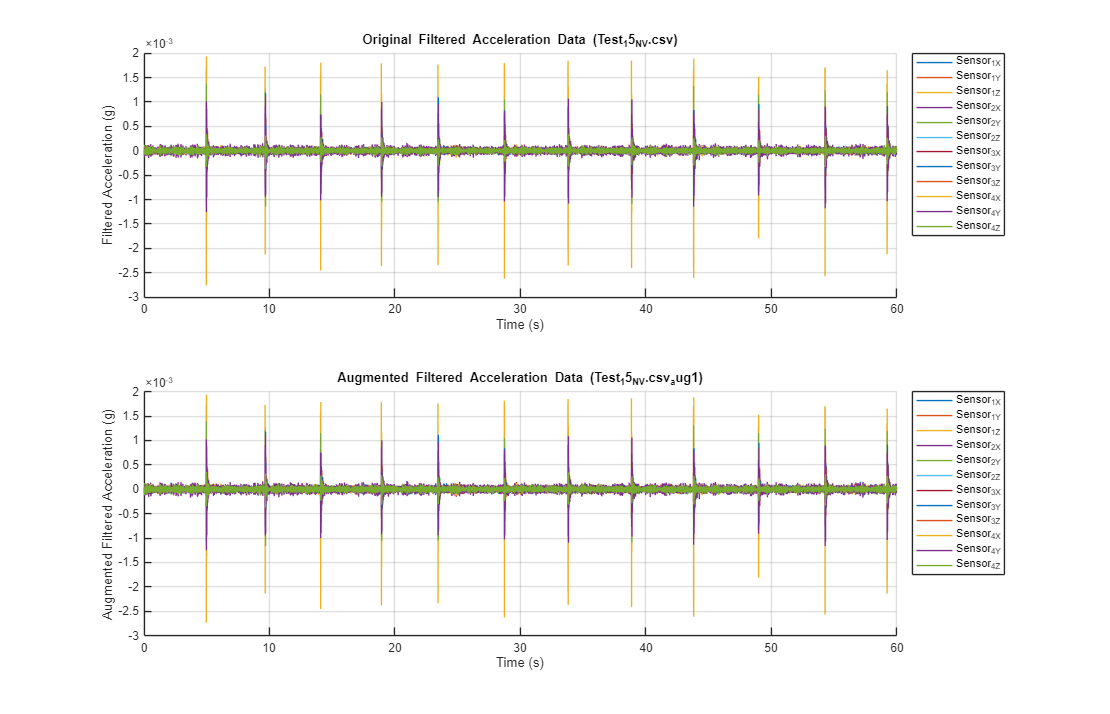


% Plotting the results for the randomly selected file
figure;
set(gcf, 'Position', [100, 100, 1400, 900]); % Set figure size

% Plot the original filtered acceleration data
subplot(2, 1, 1);
hold on;
for k = 1:size(plot_filtered_acc_data, 2)
    plot(plot_time_data, plot_filtered_acc_data(:, k), 'DisplayName', sensor_names{k + 1}); % Use the correct sensor names
end
hold off;
xlabel('Time (s)');
ylabel('Filtered Acceleration (g)');
title(sprintf('Original Filtered Acceleration Data (%s)', selected_file));
legend('Location', 'northeastoutside', 'Orientation', 'vertical');
grid on;

% Plot the augmented filtered acceleration data
subplot(2, 1, 2);
hold on;
for k = 1:size(plot_augmented_acc_data, 2)
    plot(plot_time_data, plot_augmented_acc_data(:, k), 'DisplayName', sensor_names{k + 1}); % Use the correct sensor names
end
hold off;
xlabel('Time (s)');
ylabel('Augmented Filtered Acceleration (g)');
title(sprintf('Augmented Filtered Acceleration Data (%s_aug1)', selected_file));
legend('Location', 'northeastoutside', 'Orientation', 'vertical');
grid on;


disp(['Total time for preprocessing: ', num2str(toc(total_tic)), ' seconds']);

Total time for preprocessing: 107.1368 seconds
